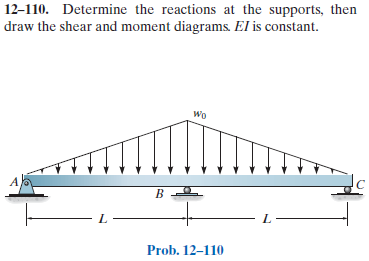

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-110P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-110P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

wo = sym('wo');
L = sym('L', 'positive');
w1 = findpoly(1, 'thru', [0 0], [L -wo]);
w2 = findpoly(1, 'thru', [L -wo], [2*L 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('reaction', 'force', 'Rc', 2*L);
b = b.add('distributed', 'force', w1, [0 L]);
b = b.add('distributed', 'force', w2, [L 2*L], [false true]);
b.L = 2*L;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,{\left(L+x\right)}^{2}\,{\left(L-x\right)}^{2}}{120\,\text{E}\,\text{I}\,L} & \text{ if }x\leq L\\ -\frac{\mathrm{wo}\,{\left(L-x\right)}^{2}\,\left(2\,L-x\right)\,{\left(3\,L-x\right)}^{2}}{120\,\text{E}\,\text{I}\,L} & \text{ if }L<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(L+x\right)\,\left(L^{2}-5\,x^{2}\right)\,\left(L-x\right)}{120\,\text{E}\,\text{I}\,L} & \text{ if }x\leq L\\ \frac{\mathrm{wo}\,\left(L-x\right)\,\left(3\,L-x\right)\,\left(19\,L^{2}-20\,L\,x+5\,x^{2}\right)}{120\,\text{E}\,\text{I}\,L} & \text{ if }L<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,x\,\left(3\,L^{2}-5\,x^{2}\right)}{30\,L} & \text{ if }x\leq L\\ -\frac{\mathrm{wo}\,\left(2\,L-x\right)\,\left(17\,L^{2}-20\,L\,x+5\,x^{2}\right)}{30\,L} & \text{ if }L<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,\left(L^{2}-5\,x^{2}\right)}{10\,L} & \text{ if }x\leq L\\ \frac{\mathrm{wo}\,\left(19\,L^{2}-20\,L\,x+5\,x^{2}\right)}{10\,L} & \text{ if }L<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x}{L} & \text{ if }x\leq L\\ -\frac{\mathrm{wo}\,\left(2\,L-x\right)}{L} & \text{ if }L<x \end{array}\right.$$

# reactions and hinges

ra 

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{L\,\mathrm{wo}}{10}\\ \mathrm{Rb} & \frac{4\,L\,\mathrm{wo}}{5}\\ \mathrm{Rc} & \frac{L\,\mathrm{wo}}{10} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

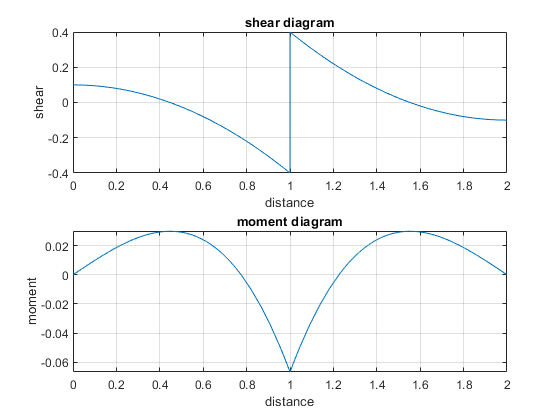

beam.shear_moment(m, v, [0 2], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;